**Reporte 2: Modelación del Movimiento de Objetos Volcánicos**

**F1008B.201:Modelación del movimiento en ciencias**

Juan Enrique Ayala Zapata  - [a01711235@tec.mx](mailto:a01711235@itesm.mx)

Humberto Mondragón García - [a01711912@tec.mx](mailto:a01711912@itesm.mx)

Mateo Minghi Vega - [a01711231@tec.mx](mailto:a01711231@itesm.mx)

Alfredo Alejandro Soto Herrera - [a01711368@tec.mx](mailto:a01711368@itesm.mx)

Introducción

En el tiro parabólico, un objeto experimenta velocidad tanto en sus componentes verticales y horizontales. Dicho esto, sólamente experimenta aceleración en el eje vertical por la fuerza de la gravedad. Las fórmulas del tiro parabólico son útiles para entender la base teórica detrás del movimiento en más de una dimensión.

Sin embargo, en un contexto real, las fórmulas físicas que describen el comportamiento de un objeto con trayectoria parabólica no son eficaces. Existen fuerzas que son normalmente eludidas y que sí tienen un impacto significativo en el trayecto del objeto.

El siguiente reporte contiene un modelo más preciso del movimiento de una partícula, considerando la fuerza resistiva, fuerza buoyante y peso que actúan en el contexto de una partícula expulsada en una erupción volcánica.

Teoría

Para modelar el movimiento de la partícula, el primer paso es definir las especificaciones de esta. 

Por motivos de simplicidad, en este modelo se considera que la partícula tiene una forma esférica, detonada por la fórmula V = 4/3pi(r)^3. El radio de cada partícula expulsada en una erupción es variable, por lo cual  es generado nuevamente en cada simulación.

Conociendo su volumen y densidad, es posible calcular su masa siguiendo la fórmula m = Po * Vo.

clear; clc; close all;

r = 0.2 + (rand * 0.4); % Radio ceniza
vol = (4/3) * pi * (r^3); % Volumen ceniza

dns_obj = 2100 + (rand * 500); % Densidad objeto
m_obj = dns_obj * vol; % Masa del objeto

La base fundamental para el modelado del movimiento son las Leyes de Newton.

Como se sabe que la partícula no se encuentra estática, sino en movimiento, es posible definir la sumatoria de sus fuerzas en sus dos componentes con las siguientes ecuaciones:

Σ*Fx = m*a *[1] 

Σ*Fy = m*g *[2]

Sin embargo, el movimiento de la partícula se ve alterado por diferentes fuerzas y factores importantes a considerar para modelar su comportamiento de manera más precisa.

En su eje horizontal (x), la partícula lleva una velocidad a la que se le opone una fuerza resistiva. Tal fuerza resistiva puede ser expresada de la siguiente forma:

*FR = -(bv)Ux *[3]

% Genera un valor aleatorio para b en el rango [10, 20]
b = 10 + (rand * 10);

% Asegura que el valor de b esté dentro del rango [10, 20]
if b > 20
    b = 20;
elseif b < 10
    b = 10;
end

c = 3; 

Donde* v *es la magnitud del vector velocidad, y Ux es la componente horizontal del vector unitario U = v/ |v|. Por lo tanto, la sumatoria de las fuerzas horizontales se expresa de la siguiente manera:

Σ*Fx = FR = m*ax *[4]

Sustituyendo como:

Σ*Fx = -(bv)Ux = m*ax *[5]

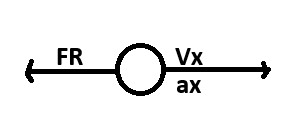

**Figura 1:** Diagrama de cuerpo libre en X.

En el eje vertical (y), la partícula experimenta una aceleración otorgada por la fuerza de gravedad, así como el peso que actúa hacia abajo; las cuales son disminuidas por la fuerza resistiva y la fuerza buoyante. La fórmula para obtener el vector peso es w = -m * g.

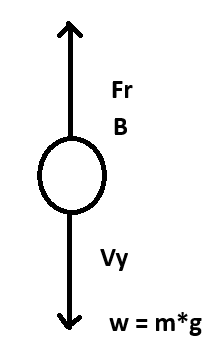

**Figura 2:** Diagrama de cuerpo libre en Y.

La fuerza buoyante es una fuerza opuesta que aparece cuando se sumerge un cuerpo en un fluido. En este caso, el aire es el fluido. Se calcula el vector con la siguiente fórmula:

B = Pf * Vo * g [6]

Donde Pf es la densidad del aire y Vo el volumen del objeto. Cabe recalcar que la densidad del aire disminuye conforme la altitud incrementa, por lo cual se puede expresar de la siguiente manera:

*ρ*=*ρ*0 * (*e)^*−*k*H *[7]

*Po* es la densidad a nivel del mar, *k* es la constante que determina la tasa de cambio exponencial (en condiciones atmosféricas normales es de 0.00012), y H es la altura.

%densidad_0 = 1.225;  %---------- densidad a nivel del mar
%k = 0.00012;   % -------------Constante de cambio exponencial
%altura = 5345;  % -------------altitud volcán

%densidad = densidad_0 * exp(-k * altura);

O si se desea simplificar el proceso, se establece la densidad como un valor preestablecido a una altitud de 5000m (este se encuentra en internet).

g=9.81; %gravedad
d_aire=0.736; %densidad aire

Tomando todos estos factores a consideración, se obitene  de manera generalizada la sumatoria de fuerzas que actúan sobre la partícula:

Σ*F = B + (m*g) + Fr = m*ax *[7]

El modelado se basa en el Método de Euler, utilizando una posición para calcular la posición anterior. Del mismo modo, se puede usar una velocidad para obtener la velocidad anterior.

Usando el método de Euler, obtenemos las siguientes fórmulas:

$V_{\textrm{yn}} =g\left(\frac{\rho_{\textrm{aire}V_{\textrm{objeto}} } }{m}-1\right)\Delta t-\left({\textrm{bv}}_{n-1} \right)\left(\frac{U_y \Delta t}{m}\right)+V_{\textrm{yn}-1}$ [8]

$V_{\textrm{xn}} =-\left(bv_{n-1} \right)\left(\frac{U_x \Delta t}{m}\right)+V_{\textrm{xn}-1}$ [9]

Dadas las velocidades, es posible calcular las posiciones:

$Y_n =Y_{n-1} -V_{\textrm{yn}-1} *\Delta t$ [10]

$X_n =X_{n-1} -V_{\textrm{Xn}-1} *\Delta t$ [11]

t_tanque = 0;

dt1 = 0.5;


nsteps = 1000;
y = zeros(1, nsteps);

% Método de Euler

y(1) = 3;

for i = 2:nsteps
    dydt = -k1 * sqrt(y1);
    y0 = y0 + dydt * dt1;    
    t_tanque = t_tanque + dt1;

    y(i) = y(i-1)+  (-k1 * sqrt(y0)) * dt;

    if y(i) < 0
        break; 
    end
end

Unrecognized function or variable 'k1'.

disp(num2str(t_tanque));

Resultados

% Gráficas
figure;
plot(x, y,'--om','MarkerFaceColor','m','MarkerSize',4,'LineWidth',2,'DisplayName','x(t))');
xlabel('Posición en X');
ylabel('Posición en Y');
title('Trayectoria de la partícula');
set(gcf,'Visible','on');
grid on;

Conclusiones

s